## Checking the discrete-time system

We load the data used in the continuous-time identifcation, because we need it in the comparisons to follows. 

clear all;
close all;
load("../../step003-open-loop-step-response/matlab/identifyTransferFunctionContinuousTimeResults.mat");
delta_t= identifyTransferFunctionContinuousTimeResults.delta_t; 
uStep= identifyTransferFunctionContinuousTimeResults.uStep; 
shifted_tData= identifyTransferFunctionContinuousTimeResults.tData;
shifted_yDeg= identifyTransferFunctionContinuousTimeResults.yData;

We convert the identified transfer function to a state space model. The exact time discretization has been carried out in a maple sheet and we load the matrices Ad, Bd that resulted there. The C and D matrix are the same for the continuous-time state space system and its discrete-time counterpart.

load('../../step003-open-loop-step-response/maple/mapleToMatlab/Ad.txt'); % provides Ad calculated with maple
load('../../step003-open-loop-step-response/maple/mapleToMatlab/Bd.txt'); % provides Bd calculated with maple
load('../../step003-open-loop-step-response/maple/mapleToMatlab/Cd.txt'); 
load('../../step003-open-loop-step-response/maple/mapleToMatlab/Dd.txt'); 
sysd= ss(Ad, Bd, Cd, Dd, delta_t); 

Let's compare the step response of the discrete-time system to the original simulation data. 

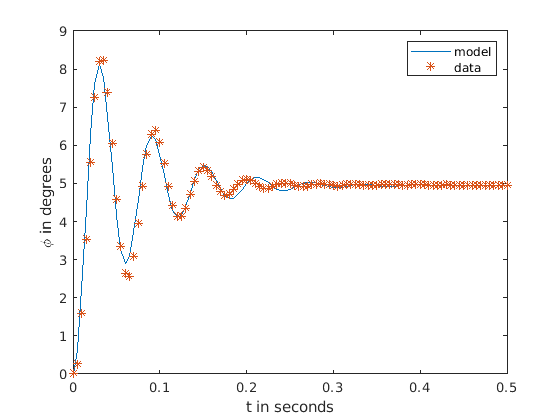

figure(); 
theStepOptions= stepDataOptions;
theStepOptions.StepAmplitude= uStep; 
[ystep, tstep, xstep]= step(sysd, theStepOptions);
plot(tstep, ystep); 
hold on;
plot(shifted_tData, shifted_yDeg, '*'); 
xlabel('t in seconds');
ylabel('\phi in degrees');
legend('model', 'data'); 
hold off; 

We also plot the angular velocity omega for visual comparison to the corresponding result for the continuous-time system.

TODO: Compare to data recorded with the arduino. 

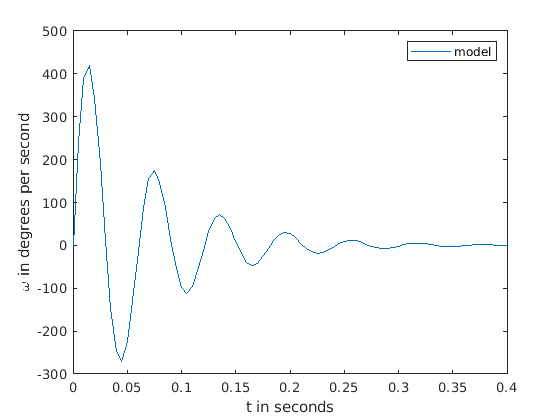

figure(); 
plot(tstep, xstep(:,2));
xlabel('t in seconds');
ylabel('\omega in degrees per second');
legend('model'); 
hold off; 

## Pole placement for state feedback

Just as for the continuous-time system, we can design a state feedback controller by pole placement. For discrete-time systems, however, it is not the open left half plane we need to confine the poles to, but it is the open unit circle. Without going into technical details we here state that the poles for the discrete-time system can be calculated from the continuous-time system poles with the 'inverse bilinear transformation'. 

continuousTimePoles= [-51, -50];
discreteTimePoles= continuousTimePoleToDiscrete(continuousTimePoles, delta_t); 

Kd= place(sysd.A, sysd.B, discreteTimePoles); 

We can now define the closed-loop system with state feedback and check it by plotting a step response. We need to calculate a scaling factor for the reference input again (Bref). 

TODO: Add diagram of closed-loop system with state feedback to explain A-BK. 

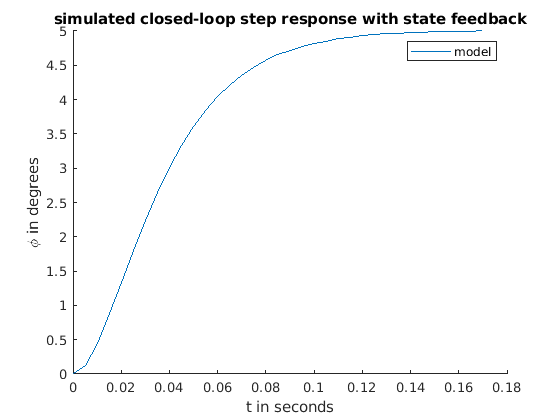

sysDiscreteClosed= ss(sysd.A-sysd.B*Kd, sysd.B, sysd.C, sysd.D, delta_t);

%
% plot closed-loop step response with prefactor
%
figure(); 
figTitle= "simulated closed-loop step response with state feedback";
title(figTitle);
hold on; 
[ySimClosed, tSimClosed]= step(sysDiscreteClosed);
bref= 1/ ySimClosed(end); % input matrix (1x1 matrix here) for scaling the reference input
plot(tSimClosed, ySimClosed*bref*uStep); % instead of multiplying step by Bref we can multiply output, since the system is linear
xlabel('t in seconds');
ylabel('\phi in degrees'); 
legend('model'); 
hold off; 

## Auxiliary functions

Functions defined here at the end of the live-script can be called in the live-script above.

function z= continuousTimePoleToDiscrete(s, Ts)
%CONTINUOUSTIMEPOLETODISCRETE Applies inverse bilinear transformation to s. 
% Converts pole s (or any other point in C) to discrete time pole with
% bilinear transformation, where Ts is the sampling time.

% if more than one pole is given in s, loop over all of them
numPoles= length(s);
if numPoles==1
    z= (2+s*Ts)/(2-s*Ts);
else
    z= zeros(1, numPoles); % allocate to avoid dynamic allocation
    for k= 1:numPoles 
        z(k)= continuousTimePoleToDiscrete(s(k), Ts);
    end
end

end